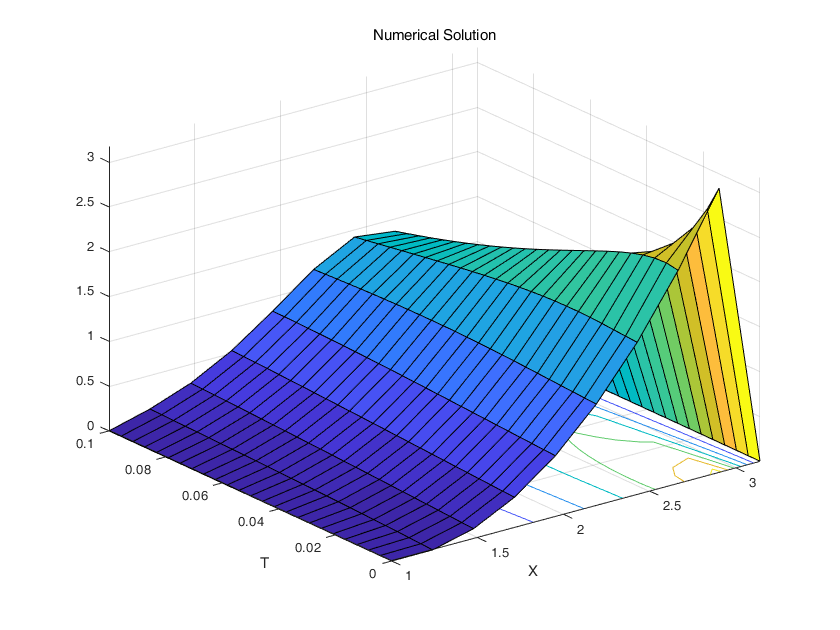

x = [1, pi];
t = [0, 0.1];
N_b = 10;
N_t = 25;
p_x = 0;
p_t = 0;
% u = @(t, x)(sin(pi*(t+x)));
% f = @(t, x)(pi*cos(pi*(t+x))+(pi^2)*sin(pi*(t+x)));
u = @(t, x)(100*exp(-(pi^2)*t).*sin(pi*x));
ut = @(x)((x-x(1)).*(x-x(2)));
ua = @(t)(0*t);
ub = @(t)(0*t);
f = @(t, x)(0*x*t);
% u = @(t, x)(exp(x) .* (1 + sin(t)));
% f = @(t, x)(exp(x) .* (cos(t) - 1 - sin(t)));



[Nu1, Au1, k1] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 1);

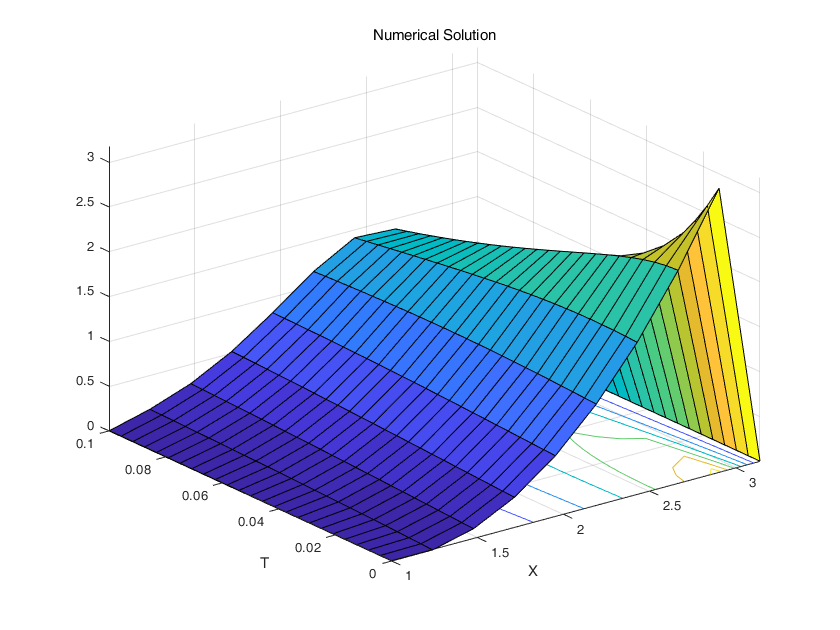


[Nu2, Au2, k2] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 2);

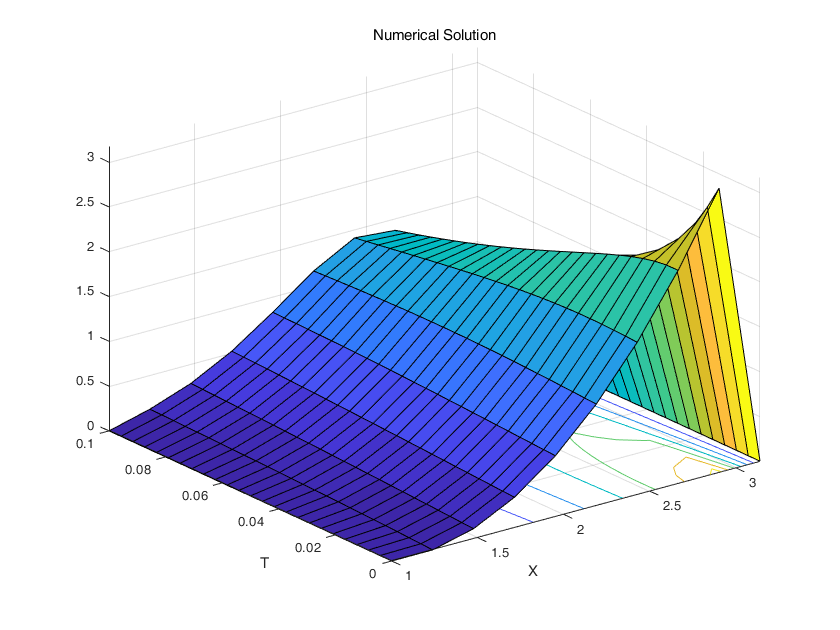


[Nu3, Au3, k3] = FD_Heat_1D(ua, ub, ut, f, x, t, N_b, N_t, p_x, p_t, 3);